# Recycling Analysis Demo

Use WasteAnalysis function to obtain the potencial saving cost of waste recycling

#### Read the Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.json";
data=ReadDataModel(file);

#### Set the parameters

if ~data.isWaste
    disp('The model has NOT waste');
    return
end
WasteFlows=convertCharsToStrings(data.WasteData.Flows);
ActiveWaste=WasteFlows(2);
States=convertCharsToStrings(data.States);
State=States(6);
CostTables='DIRECT';
if data.isResourceCost
    CostTables='ALL';
    Samples=convertCharsToStrings(data.ResourceSamples);
    ResourceSample=Samples(1);
end

#### Get Waste Analysis Results

res=WasteAnalysis(data,'ActiveWaste',ActiveWaste,'State',State,...
    'CostTables',CostTables,'ResourceSample',ResourceSample);

#### Show the Results

Show the waste allocation table and display de waste recycling graphs for direct and generalizad costs

ShowResults(res,'Table','wa');

Waste Allocation Table  (%)

 Key         QEXP      QCND
————————————————————————————
 BLR         0.00     74.97
 TRB         0.00     13.85
 PMP         0.00      1.19
 CMP       100.00      9.82
 GEN         0.00      0.17



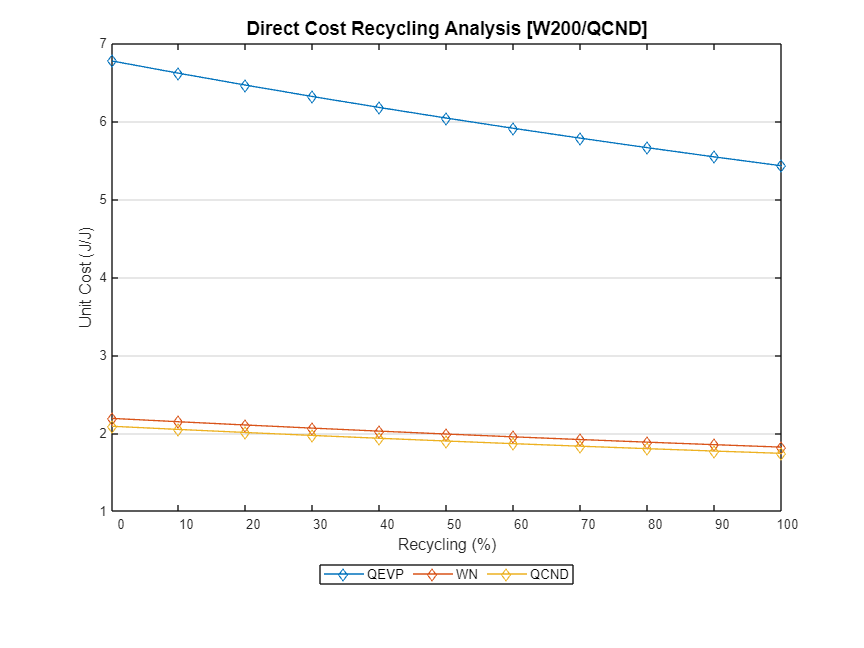

ShowGraph(res,'Graph',cType.Tables.WASTE_RECYCLING_DIRECT);

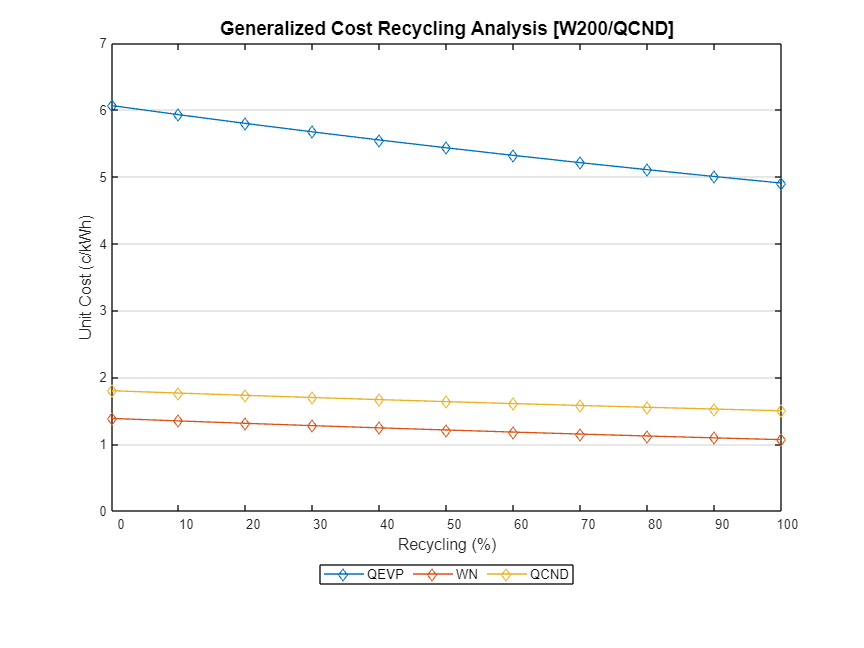

ShowGraph(res,'Graph',cType.Tables.WASTE_RECYCLING_GENERAL);